## **Use of Matlab to investigate compartmental systems**

**Kumarasinghe R D**

**210321X**

## Part 01

### **Question 01**

**Response for step input**

`function dydt = Unit_Step(t, y)`

`    A = 1;  % Step input magnitude`

`    dydt = [-0.8, 0.2; -5, -2] * y + [0; 1] * A;`

`end`

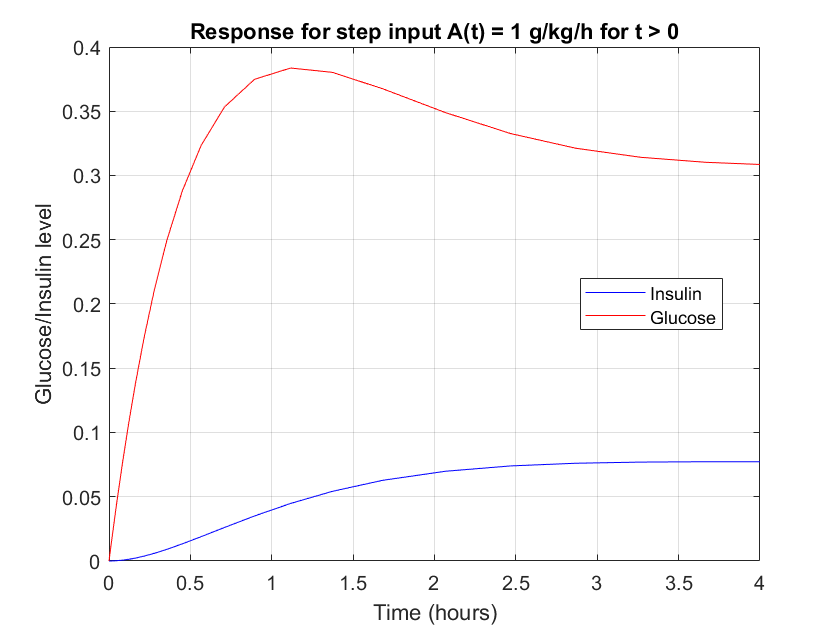

% Solve the ODEs for step input
[t, y] = ode23(@Unit_Step, [0, 4], [0, 0]);

% Plot the results for step input
figure; 
plot(t, y(:,1), '-b', 'DisplayName', 'Insulin'); % Insulin levels (y(:,1))
hold on;
plot(t, y(:,2), '-r', 'DisplayName', 'Glucose'); % Glucose levels (y(:,2))
legend('Insulin', 'Glucose', 'Location', 'best');
xlabel('Time (hours)');
ylabel('Glucose/Insulin level');
title('Response for step input A(t) = 1 g/kg/h for t > 0');
grid on;

**Response for bolus input**

`function dydt = Bolus_Input(t, y)`

`    A = 1;  % Magnitude of the bolus input`

`    dydt = [-0.8, 0.2; -5, -2] * y + [0; 1] * (t == 0) * A;`

`end`

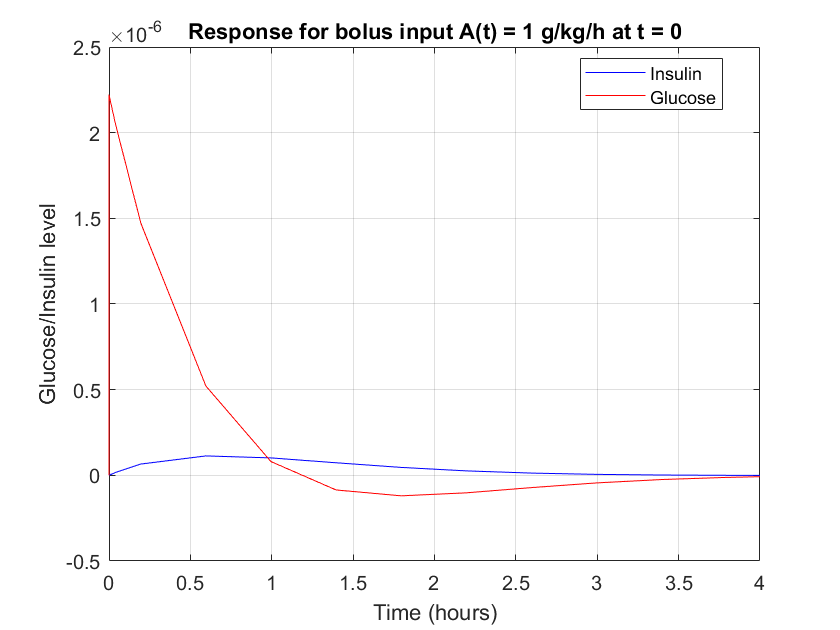

% Solve the ODEs for bolus input
[t, y] = ode23(@Bolus_Input, [0, 4], [0, 0]);

% Plot the results for bolus input
figure;
plot(t, y(:,1), '-b', 'DisplayName', 'Insulin'); % Insulin levels (y(:,1))
hold on;
plot(t, y(:,2), '-r', 'DisplayName', 'Glucose'); % Glucose levels (y(:,2))
legend('Insulin', 'Glucose', 'Location', 'best');
xlabel('Time (hours)');
ylabel('Glucose/Insulin level');
title('Response for bolus input A(t) = 1 g/kg/h at t = 0');
grid on;

**Simulating a diabetic subject with insulin infusion**

`function dydt = insuline_infused_patient(t, y)`

`    A = 1;  % Magnitude of the bolus input`

`    dydt = [-0.8, 0.2; -5, -2] * y + [0.1; 1];`

`end`

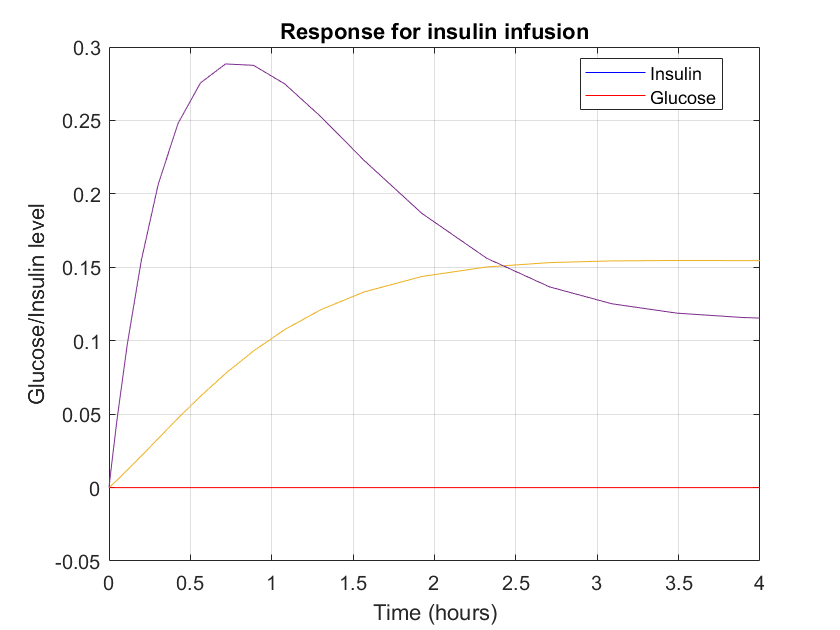

[t,y]=ode23(@insuline_infused_patient,[0 4],[0 0]);
plot(t,y);
title('Response for insulin infusion');
legend('Insulin','Glucose');

**Simulating a diabetic subject without insulin infusion**

`function dydt = diabetic(t, y)`

`    A = 1;  % Magnitude of the bolus input`

`    dydt = [-0.8, 0.01; -5, -2] * y + [0; 1] * A;`

`end`

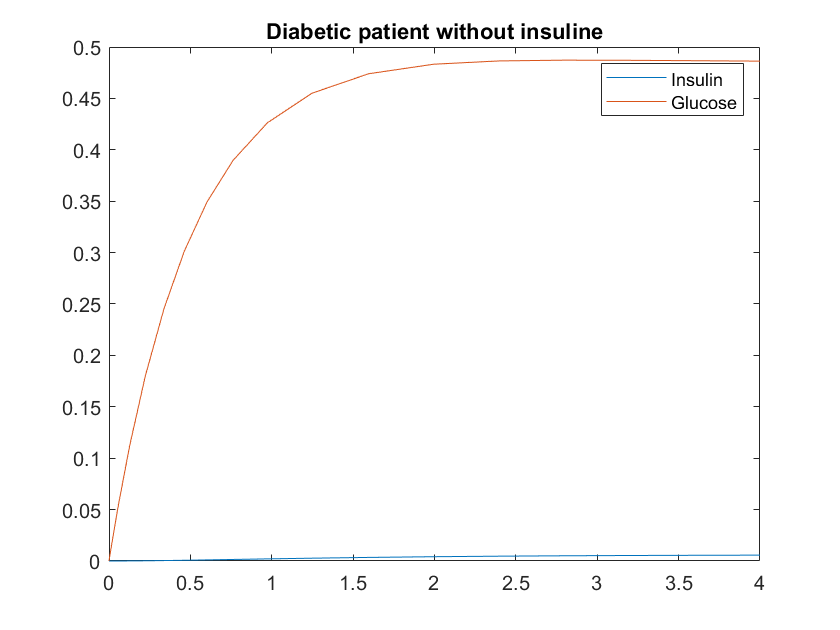

[t,y] = ode23( @diabetic, [0, 4], [0, 0]); 
plot(t,y); 
legend('Insulin','Glucose'); 
title ('Diabetic patient without insuline');

### Question 02

#### lodine intake 150 µg/day for 10 days

`function dydt = Riggs_Iodine(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.01, 0; 0, 0.01, -0.1];`

`    B = [150; 0; 0];`

`    dydt = A * y + B;`

`end`

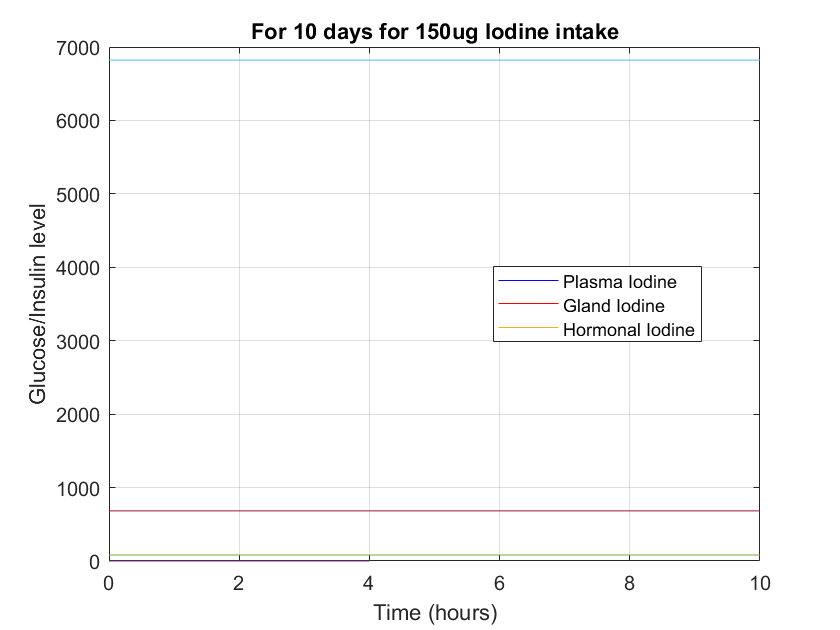

[t,y] = ode23(@Riggs_Iodine,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('For 10 days for 150ug Iodine intake');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### lodine intake 15 µg/day for 10 days

`function dydt = Riggs_Iodine_15(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.01, 0; 0, 0.01, -0.1];`

`    B = [15; 0; 0];`

`    dydt = A * y + B;`

`end`

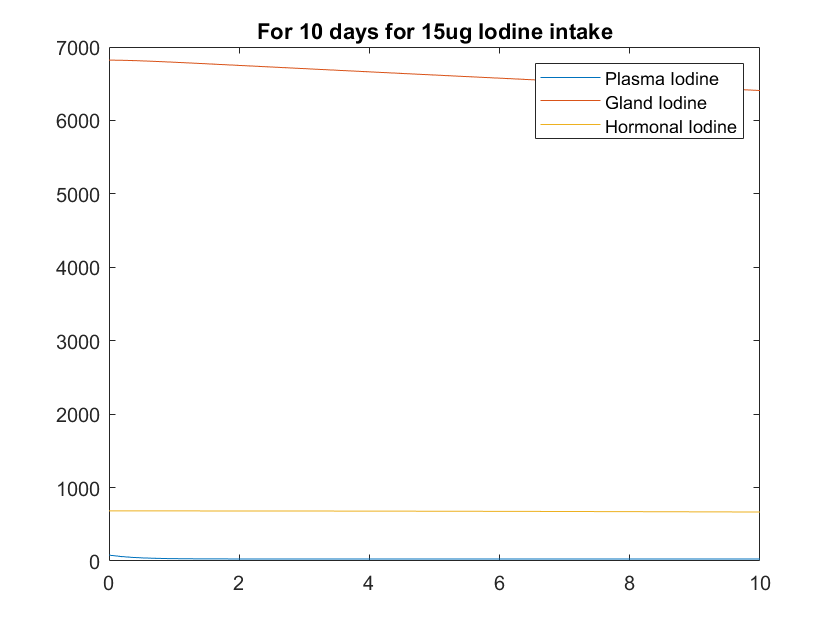

clf;
[t,y] = ode23(@Riggs_Iodine_15,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('For 10 days for 15ug Iodine intake');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### lodine intake 150 µg/day for 300 days

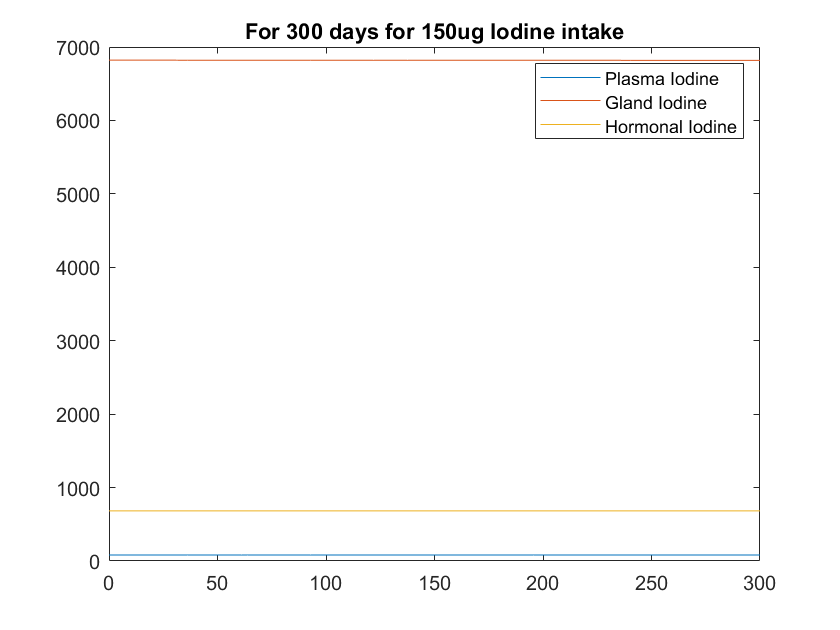

[t,y] = ode23(@Riggs_Iodine,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('For 300 days for 150ug Iodine intake');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### lodine intake 15 µg/day for 300 days

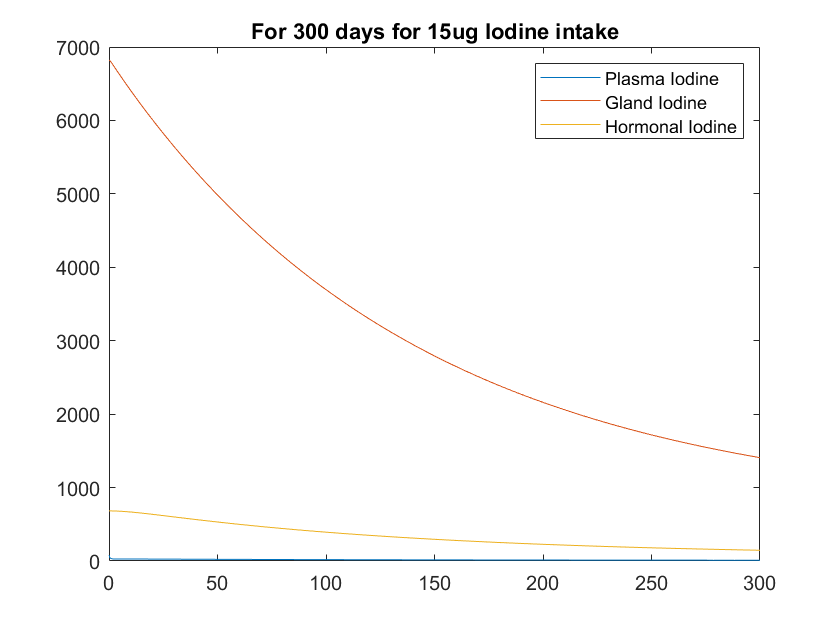

clf;
[t,y] = ode23(@Riggs_Iodine_15,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('For 300 days for 15ug Iodine intake');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### Part a

In this disease, the cells responsible for producing thyroid hormones gradually die, leading to a decline in hormone production despite normal iodine intake. This condition can be modeled using the Riggs model by reducing the k2 parameter. In the simulation, the k2 value was decreased from 0.01 to 0.005. The k2 parameter represents the rate of thyroid hormone degradation. By lowering the k2 value, the degradation of thyroid hormone is slowed down, allowing more hormone to remain available in the body, even as the hormone-producing cells deteriorate.

function dydt = Riggs_Iodine_a(t, y)

    A = [-2.52, 0, 0.08; 0.84, -0.005, 0; 0, 0.005, -0.1];

    B = [15; 0; 0];

    dydt = A * y + B;

end

**Hypothyroidism due to autoimmune thyroid disease (for 10 days)**

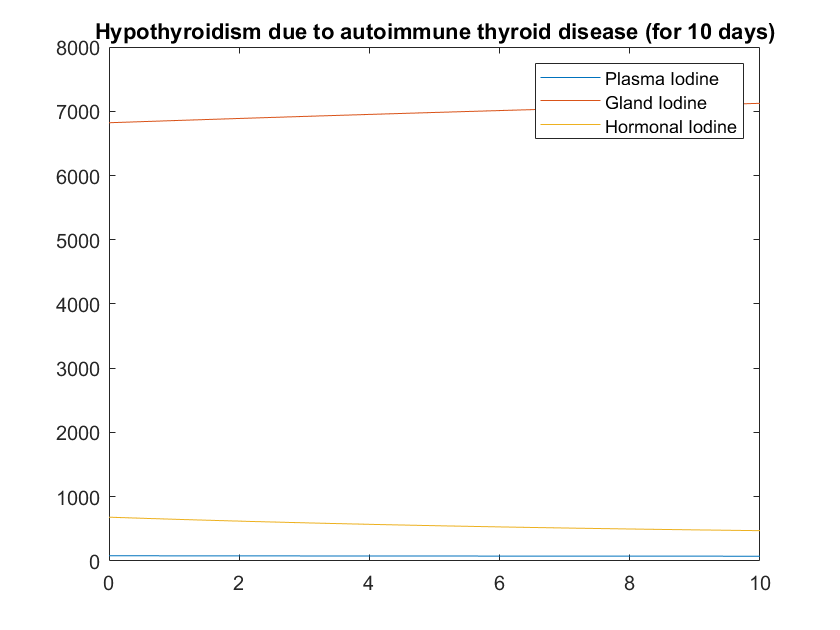

[t,y] = ode23(@Riggs_Iodine_a,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 8000]);
title('Hypothyroidism due to autoimmune thyroid disease (for 10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

**Hypothyroidism due to autoimmune thyroid disease (for 300 days)**

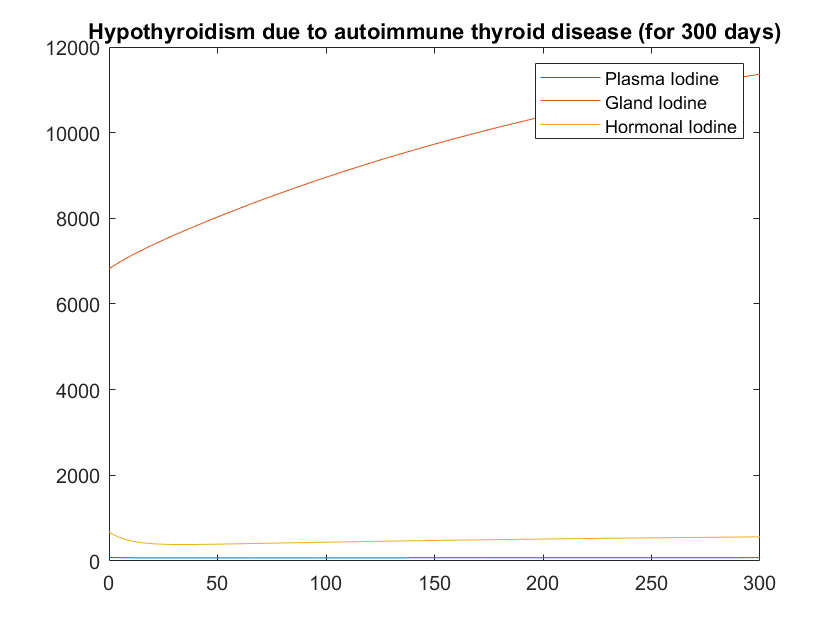

[t,y] = ode23(@Riggs_Iodine_a,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 12000]);
title('Hypothyroidism due to autoimmune thyroid disease (for 300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### Part b

This disease, caused by iodine deficiency in the diet, can be modeled using the Riggs model by decreasing the input B1(t). In the simulation, the value of B1(t) was reduced from 150 to 50, representing a significant drop in iodine intake.

`function dydt = Riggs_Iodine_b(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.01, 0; 0, 0.01, -0.1];`

`    B = [50; 0; 0];`

`    dydt = A * y + B;`

`end`

**Hypothyroidism due to  low Iodine intake (for 10 days)**

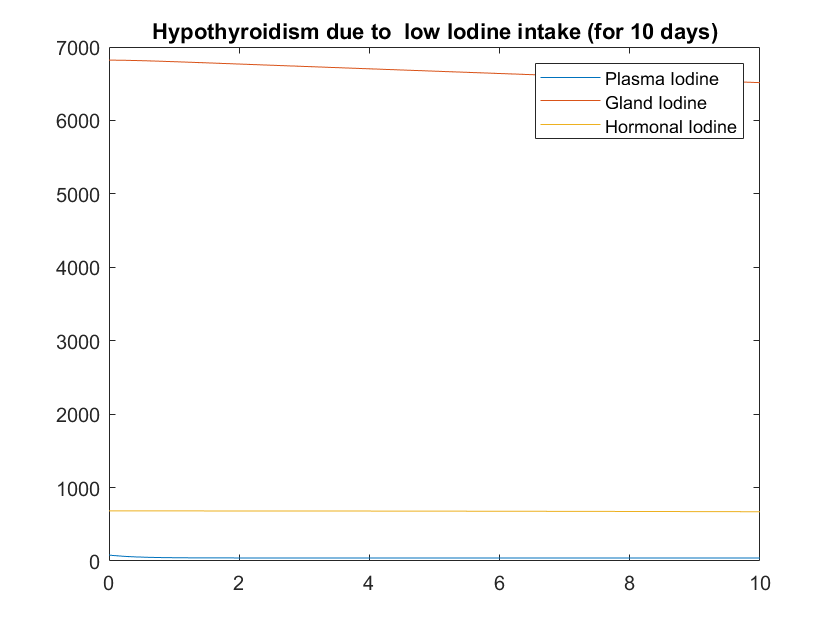

[t,y] = ode23(@Riggs_Iodine_b,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Hypothyroidism due to  low Iodine intake (for 10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

**Hypothyroidism due to  low Iodine intake (for 300 days)**

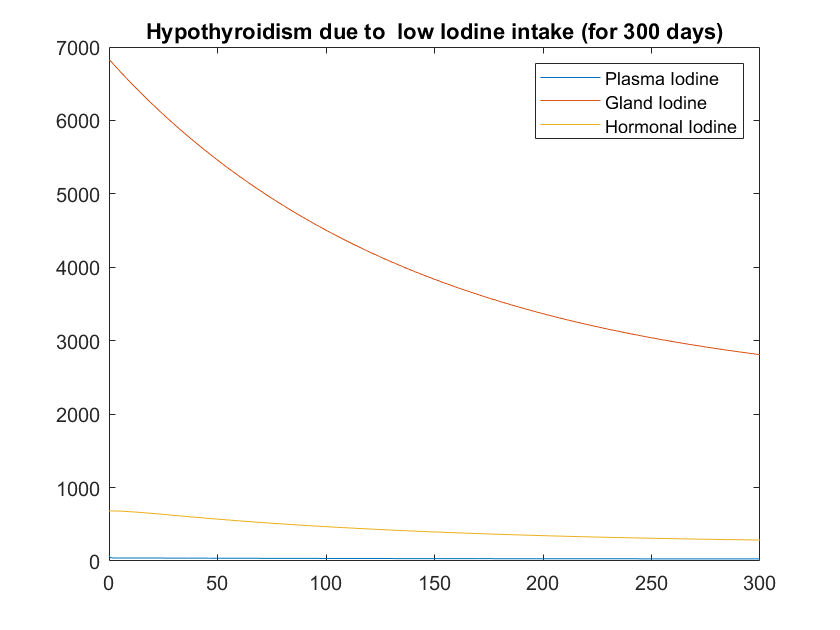

[t,y] = ode23(@Riggs_Iodine_b,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Hypothyroidism due to  low Iodine intake (for 300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### Part c

Graves' disease is a condition where the thyroid gland produces an excessive amount of thyroid hormone, leading to symptoms such as weight loss, rapid heart rate, and irregular heartbeat. The Riggs model can be utilized to simulate the effects of Graves' disease. In this simulation, the k2 parameter was increased from 0.01 to 0.08, representing an accelerated rate of thyroid hormone degradation. This adjustment results in a reduced availability of thyroid hormone in the body, which can help mitigate the symptoms associated with Graves' disease.

`function dydt = Riggs_Iodine_c(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.08, 0; 0, 0.08, -0.1];`

`    B = [150; 0; 0];`

`    dydt = A * y + B;`

`end`

**Hyperthyroidism due to Grave’s disease (for 10 days)**

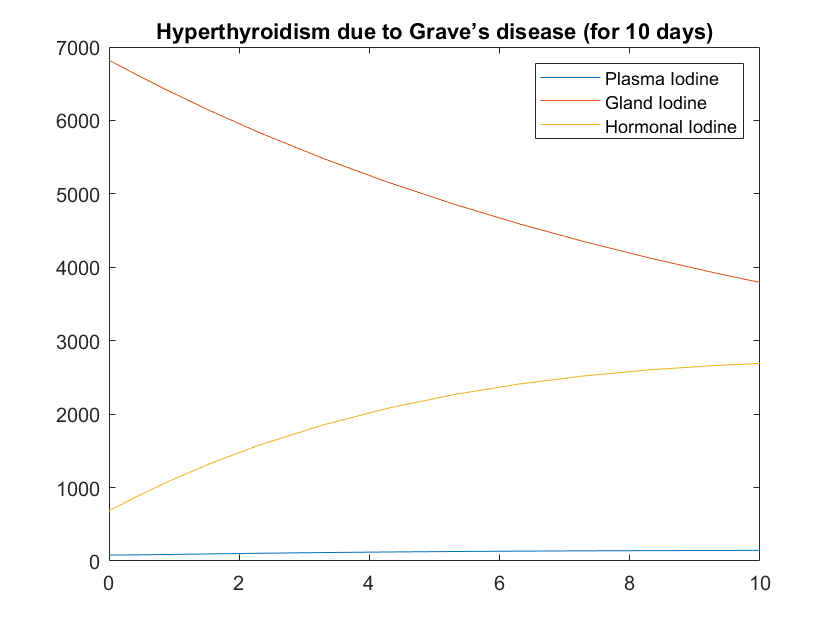

[t,y] = ode23(@Riggs_Iodine_c,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Hyperthyroidism due to Grave’s disease (for 10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

**Hyperthyroidism due to Grave’s disease (for 300 days)**

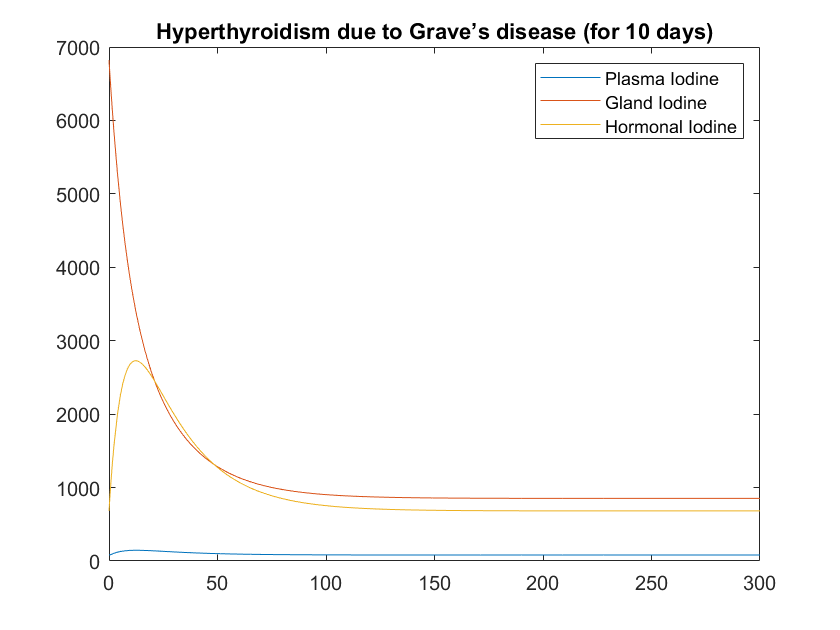

[t,y] = ode23(@Riggs_Iodine_c,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Hyperthyroidism due to Grave’s disease (for 300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

#### Part d

**Common Causes of Goitre and Tumors**

**Goitre** is an enlargement of the thyroid gland and can be classified into several types based on its etiology:

- Iodine Deficiency: This is the most common cause of goitre globally, leading to an increase in thyroid-stimulating hormone (TSH) due to low levels of thyroid hormones (T3 and T4). In iodine-deficient regions, the prevalence of goitre can be high.

- Autoimmune Disorders: Conditions like Graves' disease and Hashimoto's thyroiditis can lead to goitre formation. In Graves' disease, the thyroid is overstimulated, while in Hashimoto's, it may become inflamed and enlarged due to autoimmune attack.

- Nodular Growths: The presence of nodules within the thyroid can lead to a nodular goitre. These nodules can be benign (such as adenomas) or malignant (thyroid cancer).

- Goitrogens: Certain foods and substances (like soy and cruciferous vegetables) can inhibit thyroid hormone production, contributing to goitre development, especially in individuals with low iodine intake.

**Tumors **in the thyroid can be benign (adenomas) or malignant (thyroid carcinoma). The risk factors for thyroid tumors include:

- Family History: Genetic predisposition can increase the risk of developing thyroid cancer.

- Radiation Exposure: Previous exposure to radiation, particularly in childhood, is a known risk factor for thyroid cancer.

- Age and Gender: Thyroid cancer is more common in women and typically occurs in individuals over 40.

**Goitre**

`function dydt = Riggs_Iodine_d_Goitre(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.01, 0; 0, 0.01, -0.1];`

`    B = [30; 0; 0];`

`    dydt = A * y + B;`

`end`

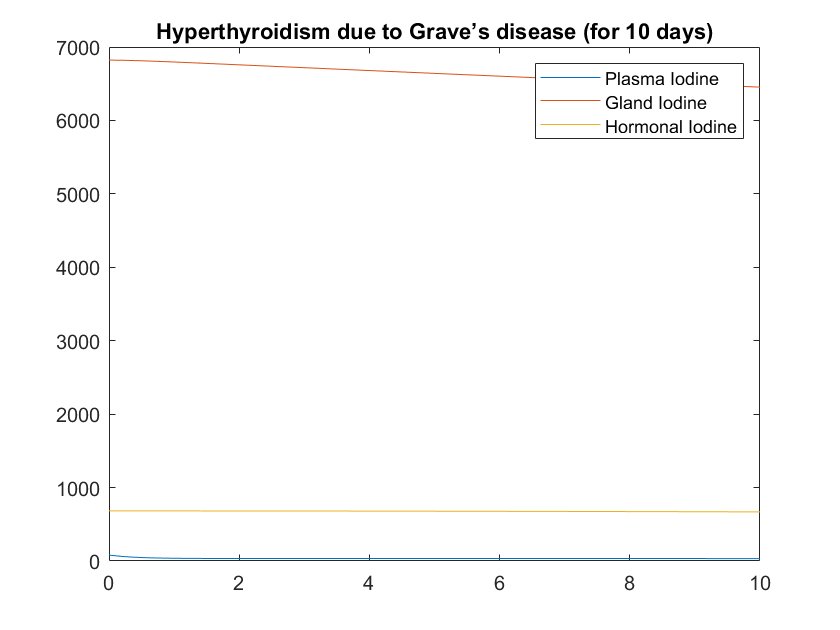

[t,y] = ode23(@Riggs_Iodine_d_Goitre,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Goitre (for 10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

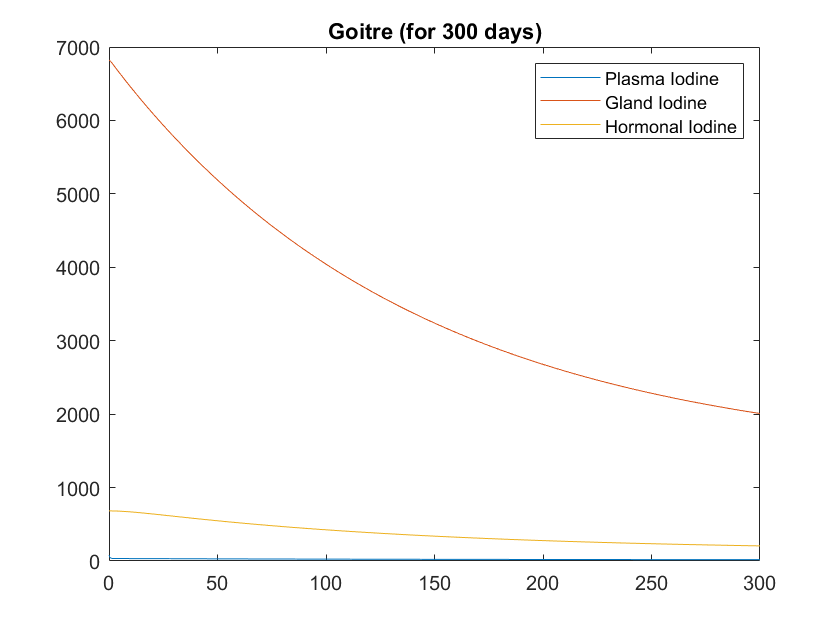

[t,y] = ode23(@Riggs_Iodine_d,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Goitre (for 300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

**Tumors**

`function dydt = Riggs_Iodine_tumor(t, y)`

`    A = [-2.52, 0, 0.08; 0.84, -0.2, 0; 0, 0.2, -0.1];`

`    B = [150; 0; 0];`

`    dydt = A * y + B;`

`end`

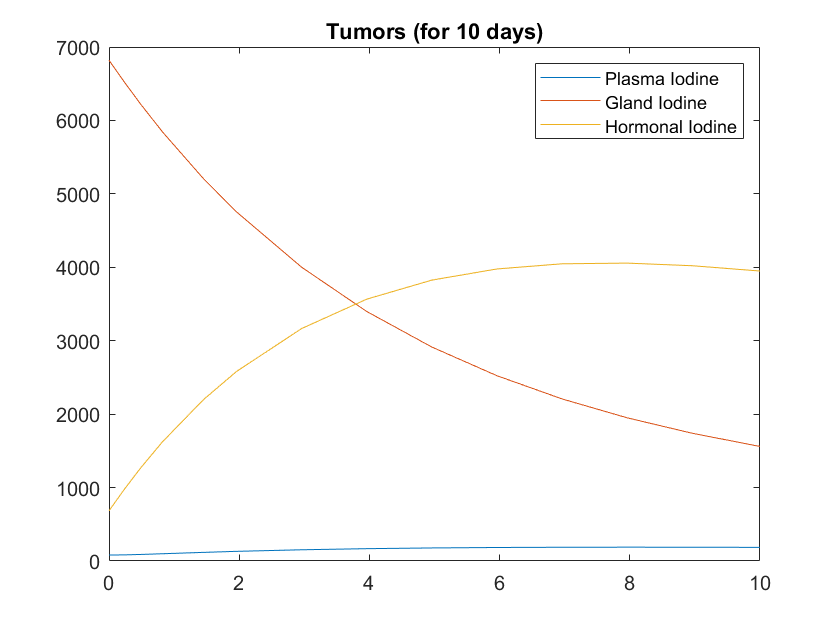

[t,y] = ode23(@Riggs_Iodine_tumor,[0 10],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Tumors (for 10 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

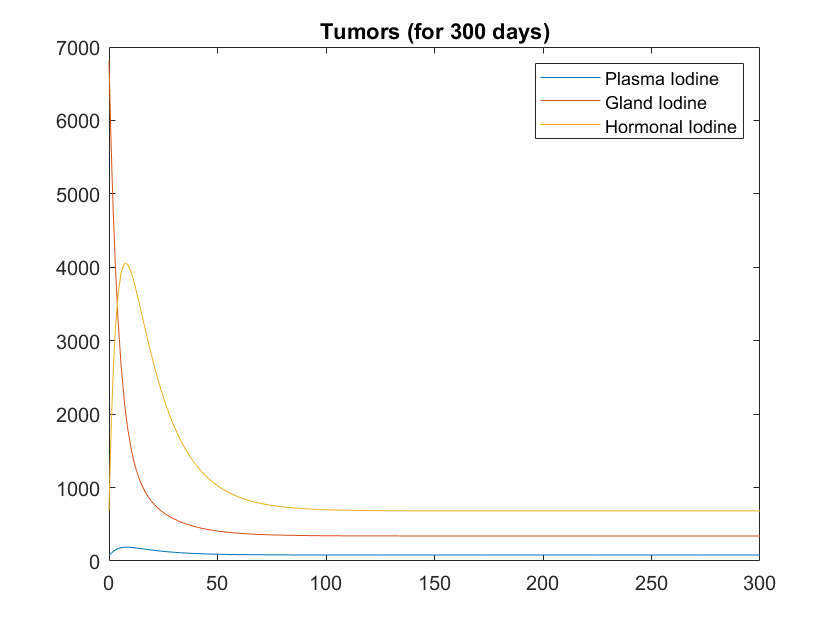

[t,y] = ode23(@Riggs_Iodine_tumor,[0 300],[81.2 6821 682]);
plot(t,y);
ylim([0 7000]);
title('Tumors (for 300 days)');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');